# 3 kHz to 18 kHz

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code generates a signal with one tone at 1200 Hz.

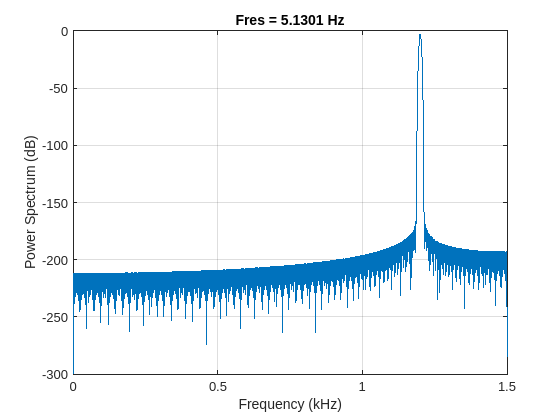

fs = 3000;
t = 0:1/fs:0.5;
sig = sin(2*pi*1200*t);
pspectrum(sig, fs)

## Task 1

To upsample a signal without an anti-imaging filter, you can use the `upsample` function:

`y` `=` `upsample``(``x``,``n``)`

where `n` is an integer upsampling factor.

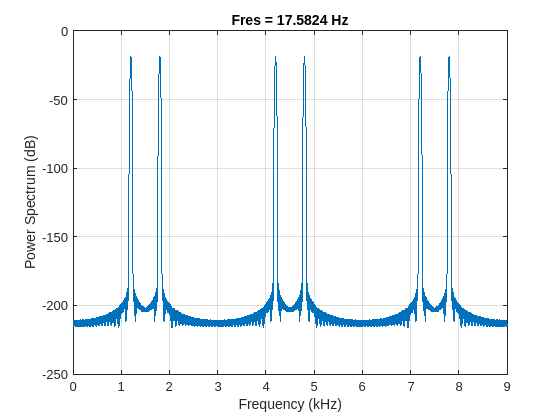

sigbad = upsample(sig, 6);
pspectrum(sigbad, fs*6);

## Task 2

All the tones above 1500 Hz are images. To reduce the imaging, you can use an anti-imaging filter after upsampling. The `resample` function will include this filter for you, but to see how it works first, you can try making your own.

`y` `=` `upsample``(``x``,``n``)`

`z` `=` `lowpass``(``y``,``fsOld``/``2``,``fs``)`

`fsOld``/``2` is Nyquist frequency before upsampling.

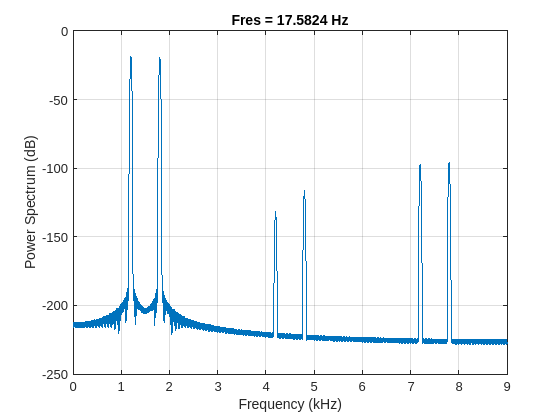

sigfilt = lowpass(sigbad, 1500, fs*6);
pspectrum(sigfilt, fs*6);

## Task 3

The power of the image at 1.8 kHz decreased by about 2 dB. Tones that were located further away decreased by about 100 dB.

Now you can try using the `resample` function to interpolate the signal:

`y` `=` `resample``(``x``,``p``,``q``)`

`p` and `q` are integer resample factors. The output signal `y` has `p``/``q` samples from `x`.

When you interpolate, `q` is `1` because the output will have `p``/``1` samples.

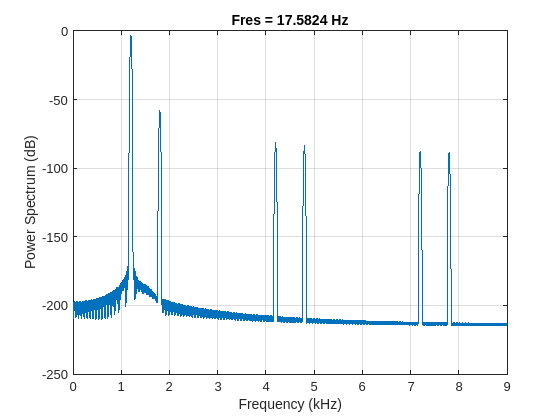

siggood = resample(sig, 6, 1);
pspectrum(siggood, fs*6)

## Further Practice

Change this to `true` to hear the tones.

playsound = true;
if playsound
    soundsc(sig, fs)
    pause(1.2)
    
    soundsc(sigbad, fs*6)
    pause(1.2)
    
    soundsc(siggood, fs*6)
end